# Characterization of metasurfaces WITHOUT segmentation 

clear; clc; close all;

addpath '/Users/mahsatorfeh/Desktop/MESTI.m-main/src'
addpath '/Users/mahsatorfeh/installation_files/MUMPS_5.5.1/MATLAB'
% addpath '/Users/mahsatorfeh/installation_files/MUMPS_5.7.1/MATLAB'


fig_font_size = 12;
plot_fig = true;
plot_segments = true;                 % Flag to plot all response of all segment 
                                      % For large number of segments it is
                                      % recommended be false, as the time
                                      % consumption for plottings will be
                                      % considerable

### System parameters and general setup

% Parameters of the structure

focal_length = 30;                    % Focal length of the metalens [micron]
wavelength = 0.532;                   % Vacuum wavelength [micron]

n_air    = 1.0;                       % Refractive index of air on the right
n_silica = 1.46;                      % Refractive index of silica substrate on the left
n_TiO2   = 2.43;                      % Refractive index of TiO2 ridges
dx = wavelength/40;                   % Discretization grid size [micron]
Lambda = 18*dx                        % Unit-cell size (period) [micron]

Lambda = 0.2394

L  = 0.6;                             % Thickness of the metalens [micron]

# Inputs to the structures

### Widths and padding ratios 

W_tot_over_wavelenght = 200%139%120%99%139%225    % width of whole structure over wavelength 

W_tot_over_wavelenght = 200

W_seg_over_wavelenght = 60%69.75      % width of segments over wavelength 

W_seg_over_wavelenght = 60


pad_big =  0.5                       % Padding ratio of big structure   % @@@@@@

pad_big = 0.5000



W_overlap_over_wavelenght = 15%30.69

W_overlap_over_wavelenght = 15

%overlap_to_segment_ratio_init = 0.44 % Overlapping ratio 
                                      % q = W_overlap/W_segment
                                      % must be between 0 and 1

### Flags 

center_y = true;                      % Flag for centering the reference position point (for symmetry) 
do_compression = true;                % Flag for compression
use_B_L_comp_DFT = false;             % Flag for updating the Fourier transform   
do_Hann = true;                       % Flag for using Hann window
do_pad = true;                        % Flag for padding angular channels



### Force W_tot to be integer number of unit-cells for easy calc

n_meta_atom_big = floor(W_tot_over_wavelenght *wavelength/ Lambda) 

n_meta_atom_big = 444

W_tot_over_wavelenght = n_meta_atom_big * Lambda /wavelength

W_tot_over_wavelenght = 199.8000

### Sanity checks of input widths

if W_tot_over_wavelenght < W_seg_over_wavelenght
    error('W_tot < W_seg')
elseif W_seg_over_wavelenght < W_overlap_over_wavelenght
    error('W_seg < W_overlap')
end

if W_overlap_over_wavelenght/W_seg_over_wavelenght > 0.5
    warning('W_overlap/W_seg is big -> Causing two segments that are not adjacent have overlapping');
end

% W_seg and W_overlap are preferred not to be too small
min_seg_size = 2*wavelength;          
min_overlap_size = wavelength;       

if W_seg_over_wavelenght < (min_seg_size/wavelength)
    error('W_seg is too small')
end
if W_overlap_over_wavelenght < (min_overlap_size/wavelength)
    error('W_overlap is too small')
end


# Finding required sizes for segments and overlapped areas

### Number of unit-cell pixels 

nx_unitcell = ceil(L/dx)              % Number of pixels of one unit cell in the x direction

nx_unitcell = 46

nx_metalens = nx_unitcell             % Number of pixels of the metalens in the x direction

nx_metalens = 46


ny_unitcell = Lambda/dx               % Number of pixels of one unit-cell in the y direction

ny_unitcell = 18

### Number of big, segment and ovelrapping pixels     @@ segments can go through meta-atoms right now

ny_metalens_big = round( W_tot_over_wavelenght * wavelength/dx )  % Num of pixels of the metalens in the y direction             

ny_metalens_big = 7992

ny_seg = ceil( W_seg_over_wavelenght * wavelength/dx )            % Num of pixels of the segment in the y direction

ny_seg = 2400

ny_overlap = ceil( W_overlap_over_wavelenght * wavelength/dx )    % Num of pixels of the overlap in the y direction 

ny_overlap = 600

### Ensuring  segment < total structure  &  overlap < segment

if ny_metalens_big <= ny_seg                
    error('ny_metalens_big <= ny_seg');
elseif ny_seg <= ny_overlap 
    error('ny_seg <= ny_overlap');
end

### Ensuring a symmterical segmentation

num_seg = ceil( (ny_metalens_big - ny_overlap) / (ny_seg-ny_overlap) )  % Number of segments

num_seg = 5


% Force the segments to have symmetrical sizes
ny_tot_middle_segs = (num_seg-2)*ny_seg - (num_seg-3)*ny_overlap  

ny_tot_middle_segs = 6000

is_odd_ny_Middle = rem(ny_tot_middle_segs , 2)

is_odd_ny_Middle = 0

is_odd_ny_big = rem(ny_metalens_big , 2)

is_odd_ny_big = 0


if is_odd_ny_big ~= is_odd_ny_Middle

    if rem(num_seg , 2) == 0
        ny_overlap = ny_overlap + 1
    elseif rem(num_seg , 2) == 1
        ny_seg = ny_seg + 1
    end

    num_seg = ceil( (ny_metalens_big - ny_overlap) / (ny_seg-ny_overlap) ) 
    ny_tot_middle_segs = ( (num_seg-2)*ny_seg - (num_seg-3)*ny_overlap ) 

end

ny_each_end_only = (ny_metalens_big - ny_tot_middle_segs)/2

ny_each_end_only = 996

ny_seg_on_ends = ny_overlap + ny_each_end_only

ny_seg_on_ends = 1596



if ny_seg_on_ends <= min_seg_size/dx
    warning('ny_each_end_only is too small')
    num_seg = num_seg - 2
    ny_tot_middle_segs = ( (num_seg-2)*ny_seg - (num_seg-3)*ny_overlap ) 
    ny_each_end_only = (ny_metalens_big - ny_tot_middle_segs)/2
    ny_seg_on_ends = ny_overlap + ny_each_end_only
end

### Calculate number of channels (sampling points) 

NL_big_calc = N_L_finder(W_tot_over_wavelenght, wavelength , pad_big)

NL_big_calc = 601


NL_no_pad_seg_calc = N_L_finder(W_seg_over_wavelenght, wavelength , 0)

NL_no_pad_seg_calc = 121

NL_no_pad_seg_side_calc = N_L_finder(ny_seg_on_ends*dx/wavelength, wavelength , 0)

NL_no_pad_seg_side_calc = 81

NL_no_pad_overlap_calc = N_L_finder(W_overlap_over_wavelenght, wavelength , 0)

NL_no_pad_overlap_calc = 31

### Final sanity checks

if ny_each_end_only<0 
    error('n_each_end_only < 0')
elseif ny_each_end_only-floor(ny_each_end_only)~=0
    error('n_each_end_only is not integer')
elseif (num_seg-2)*ny_seg - (num_seg-3)*ny_overlap + 2*ny_each_end_only - ny_metalens_big ~= 0
    error('(num_seg-2)*ny_seg - (num_seg-3)*ny_overlap + 2*n_each_end_only  ~=  ny_metalens_big')
end


if NL_no_pad_seg_calc < NL_no_pad_overlap_calc   % @@@@@@ %overlap_to_segment_ratio >= 1-ny_metalens_big/(ny_seg*NL_big_calc) % or if NL_seg < NL_over + 1
    error('W_overlap/W_seg is too large');
end

### Final sizes

W_tot_over_wavelenght = ny_metalens_big * dx/wavelength    % Final width of big structure over wavelength

W_tot_over_wavelenght = 199.8000

W_seg_over_wavelenght = ny_seg * dx/wavelength             % Final width of segment over wavelength

W_seg_over_wavelenght = 60

W_overlap_over_wavelenght = ny_overlap * dx/wavelength     % Final widht of overlap area

W_overlap_over_wavelenght = 15


% L = nx_metalens*dx                                       % Final thickness of metalens (meta-atoms only)

### Index of segments: start & end

ind_ny_segs = zeros(num_seg , 2);

ind_ny_segs(1,:)   =   [1 , ny_seg_on_ends];
ind_ny_segs(num_seg,:)  =  [ny_metalens_big-ny_seg_on_ends+1 , ny_metalens_big];

for seg_cnt = 2:num_seg-1
    ind_ny_segs(seg_cnt,:) = [ ny_seg_on_ends  + (seg_cnt-2)*ny_seg - (seg_cnt-1)*ny_overlap + 1 ...
                                    , ny_seg_on_ends  + (seg_cnt-1)*ny_seg - (seg_cnt-1)*ny_overlap];
end


ny_segs = ind_ny_segs(:,2) - ind_ny_segs(:,1) + 1;
if max(abs( ny_segs - flip(ny_segs) )) ~= 0
    error('Segment sizes are not symmetrical')
end

ny_segs

ny_segs =         1596
        2400
        2400
        2400
        1596


### Final plotting on sizes

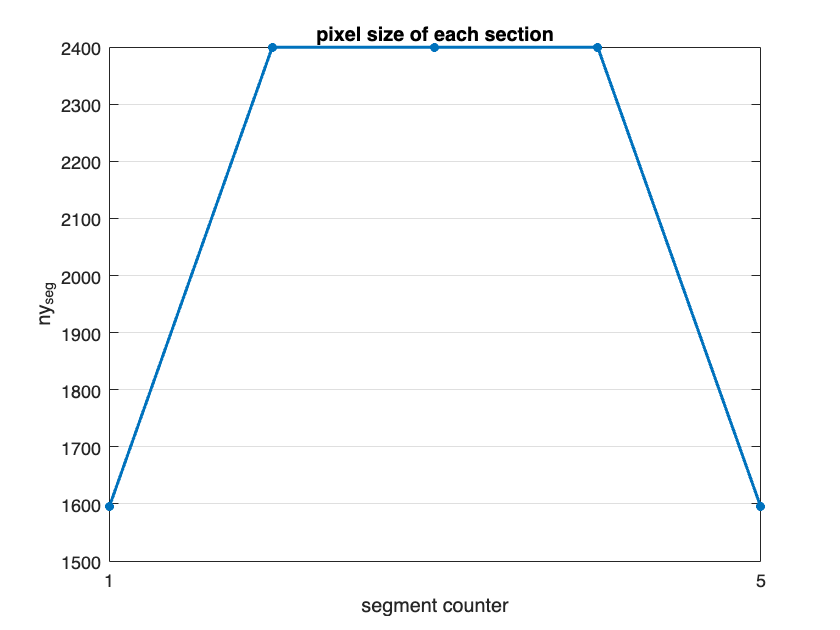

figure;
    plot(ny_segs,'-*','LineWidth',2); title('pixel size of each section'); 
    ylabel('ny_{seg}');  set(gca,'fontsize',fig_font_size);  set(gcf,'color','w'); 
    xlabel('segment counter');  xticks([1,num_seg]); xlim([1,num_seg]); grid on;



plot_1D_Schematic(ny_metalens_big , ind_ny_segs , num_seg);

max( 2D_Schem - rot90(2D_Schem,2) ) = 0.000000 

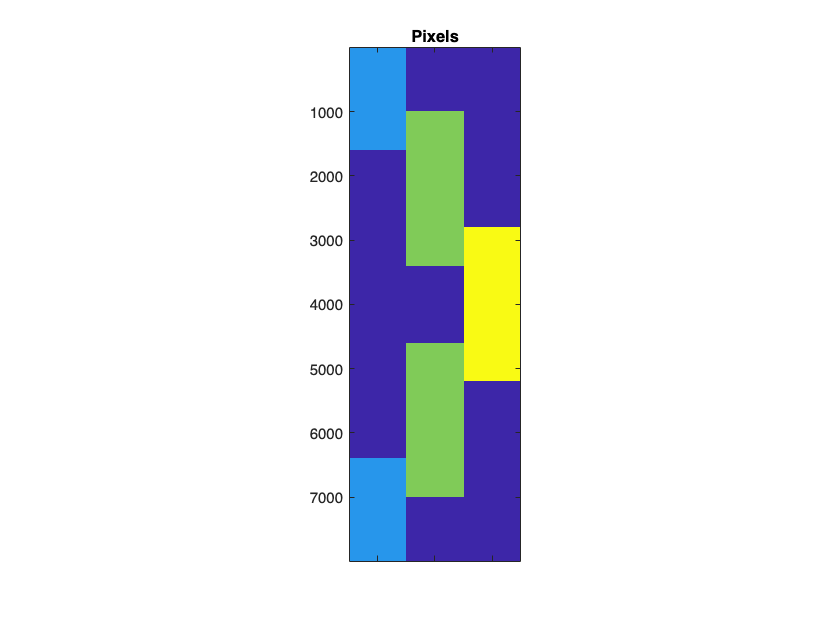

    title('Pixels'); pbaspect([1 3 1]); ax = gca; set(ax, 'XTickLabel', []);

clearvars seg_cnt is_odd_ny_big is_odd_ny_Middle
% save parameters

# Big structure 

W = W_tot_over_wavelenght * wavelength  % @@@@@@ n_meta_atom_big * Lambda

W = 106.2936

pad_ratio = pad_big

pad_ratio = 0.5000


NA = sin(atan(W/2/focal_length))        % Numerical aperture

NA = 0.8708


n_meta_atom = ceil(W/Lambda)            % Number of meta-atoms

n_meta_atom = 444


% Parameters for the input and output
W_in  = W                               % Width of the incident wave [micron]   @@@@@@

W_in = 106.2936

W_out = W          %  + 40*wavelength;  % Width where we sample the transmitted field [micron]

W_out = 106.2936

                                        % (Larger W_out ensures all transmitted light is captured)   

% Parameters for input/output matrix compression
if do_compression
    % The compression procedure is described in supplementary section 5 of the APF paper:
    % 1. Optionally pad extra channels to the input/output.
    % 2. Optionally scale the the channels with weights q.
    % 3. Fourier transform the input/output matrices so they become spatially localized.
    % 4. Truncate the transformed input/output matrices within a window size.
    % These parameters should be chosen based on the desired level of accuracy;
    % see Supplementary Fig 10 of the APF paper.

    % Whether or not to use the Hann window function for the scaling weight q
    % Set use_Hann_window = false to skip scaling.
    % As shown in Supplementary Fig 10, using the Hann window generally reduces
    % the compression error significantly.
    if do_Hann
        use_Hann_window = true; %true;
    else
        use_Hann_window = false;
    end
    % pad_ratio = (number of extra channels to pad)/(number of channels of interest)
    % Set pad_ratio = 0 to skip padding.
    % When Hann window is used, it is important to also pad extra channels;
    % otherwise the compression error may go up instead of down.
    % But too much padding can increase computing time and memory usage if
    % nnz(B) or numel(S) grows larger than nnz(A). A padding_ratio of 0.5 is
    % a reasonable choice.
    if do_pad
        if do_Hann == false
            error('Padding is not recommended without Hann window');
        end
        pad_ratio_L = pad_ratio;   
        pad_ratio_R = pad_ratio_L; 
    else
        pad_ratio_L = 0;
        pad_ratio_R = 0;
    end
    % trunc_width_over_lambda = (truncation window width)/wavelength
    % Larger truncation window gives lower compression error but increases
    % nnz(B). The peak width of the Fourier-transformed input/output matrices is
    % inversely proportional to the momentum space range spanned by the
    % input/output plane waves (counting both the target channels and the padded
    % channels), so if fewer input/output channels are considered, a larger
    % truncation width should be used. A window of 10*lambda is typically more
    % accurate than enough.
    trunc_width_over_lambda_L = 10;     % @@@@@@
    trunc_width_over_lambda_R = 10;
end

syst.length_unit = 'µm';
syst.wavelength = wavelength;
syst.dx = dx;
% syst.PML.npixels = 20;  % Number of PML pixels (on all four sides)
syst.PML = get_optimal_PML(wavelength/dx) % @ PML_HoChun  20;  % Number of PML pixels (on all four sides)

syst = struct with fields:
    length_unit: 'µm'
     wavelength: 0.5320
             dx: 0.0133
            PML: [1×1 struct]


### Build the relative permittivity profile of the system

% Number of pixels
% nx_unitcell = ceil(L/dx);                 % Number of pixels of one unit cell in the x direction
% ny_unitcell = Lambda/dx;                  % Number of pixels of one unit cell in the y direction
% nx_metalens = nx_unitcell                 % Number of pixels of the metalens in the x direction
ny_metalens = ny_metalens_big;              % n_meta_atom*ny_unitcell     % Number of pixels of the metalens in the y direction
%                            
% Mid-cell position of the meta-atoms in the y direction [micron] 
y_mid_cell = ((0.5:n_meta_atom) - (n_meta_atom/2))*Lambda;

% Target transmission phase shift of each meta-atom, meant to focus normal-incident light

target_phase = (2*pi/wavelength)*(focal_length - sqrt(focal_length^2 + y_mid_cell.^2));

% Load the ridge widths and associated phase shifts from the meta-atom example.
% ridge_width_design_list is a row vector storing the ridge widths of 8 meta-atoms, [nm].
% phi_over_pi_design_list = ((pi/4)*(0:7))/pi
load('../2d_meta_atom/meta_atom.mat', 'ridge_width_design_list', 'phi_over_pi_design_list');
ridge_width_design_list = ridge_width_design_list/1e3; % convert from nm to micron
ridge_height = L; % Ridge height is the thickness of the metalens
n_phases = numel(ridge_width_design_list); % Number of discrete phase shifts (8)

% epsilon_library(:,:,ii) stores the permittivity profile of the ii-th meta-atom in that list
epsilon_library = zeros(ny_unitcell, nx_unitcell, n_phases);
for ii = 1:n_phases
    % Build the permittivity profile for ii-th meta-atom.
    epsilon_library(:,:,ii)= build_epsilon_meta_atom(dx, n_air, n_TiO2, ...
        ridge_width_design_list(ii), ridge_height, Lambda);
end

% For each meta-atom in the metalens, assign it to be one of those 8 based on its target phase shift
% The 2*pi phase (same as 0 phase) is added for the interpolation
ind_meta_atom = interp1( ...
    [phi_over_pi_design_list, 2], ...
    [1:n_phases, 1], ...
    mod(target_phase, 2*pi)/pi, 'nearest');

% Construct the permittivity profile of the metalens by assigning the permittivity 
% profile of each meta-atom to its position on the metalens
epsilon_metalens = zeros(ny_metalens, nx_metalens);
for ii = 1:n_meta_atom
    ind_y = (ii-1)*ny_unitcell+(1:ny_unitcell); % The range of indices in the y direction for ii-th meta-atom
    epsilon_metalens(ind_y,:) = epsilon_library(:,:,ind_meta_atom(ii));
end

% W_out > W, so we will pad extra pixels
ny_R_extra_half = round((W_out-W)/dx/2)

ny_R_extra_half = 0


% Number of pixels in the y direction for the source (on the left) and the projection (on the right)
ny_L = ny_metalens

ny_L = 7992

ny_R = ny_metalens + 2*ny_R_extra_half

ny_R = 7992


W_in  = ny_L*dx % Actual width of the incident wave [micron] 

W_in = 106.2936

W_out = ny_R*dx % Actual width where we sample the transmitted field [micron] 

W_out = 106.2936


% Include homogeneous space and PML to the permittivity profile.
epsilon_L = n_silica^2; % Relative permittivity on the left
epsilon_R = n_air^2;    % Relative permittivity on the right and on the top & bottom
nPML = syst.PML.npixels;%npixels; @PML_HoChun 
% Extra number of pixels for four sides
nx_extra_left = 1 + nPML; % Add one pixel of free space for source and projection
nx_extra_right = nx_extra_left;
ny_extra_low = ny_R_extra_half + nPML;
ny_extra_high = ny_extra_low;

ny_tot = ny_metalens + ny_extra_low + ny_extra_high % Total number of pixels in the y direction

ny_tot = 8012


% Construct the permittivity profile over all simulation domain (including
% metalens, PML, and extra padded pixels)
syst.epsilon = [epsilon_L*ones(ny_tot, nx_extra_left), ...
[epsilon_R*ones(ny_extra_low,nx_metalens); epsilon_metalens; epsilon_R*ones(ny_extra_high,nx_metalens)], ...
epsilon_R*ones(ny_tot, nx_extra_right)];

clear epsilon_library ind_meta_atom phi_over_pi_design_list ridge_width_design_list

### Final check on refractive index profile

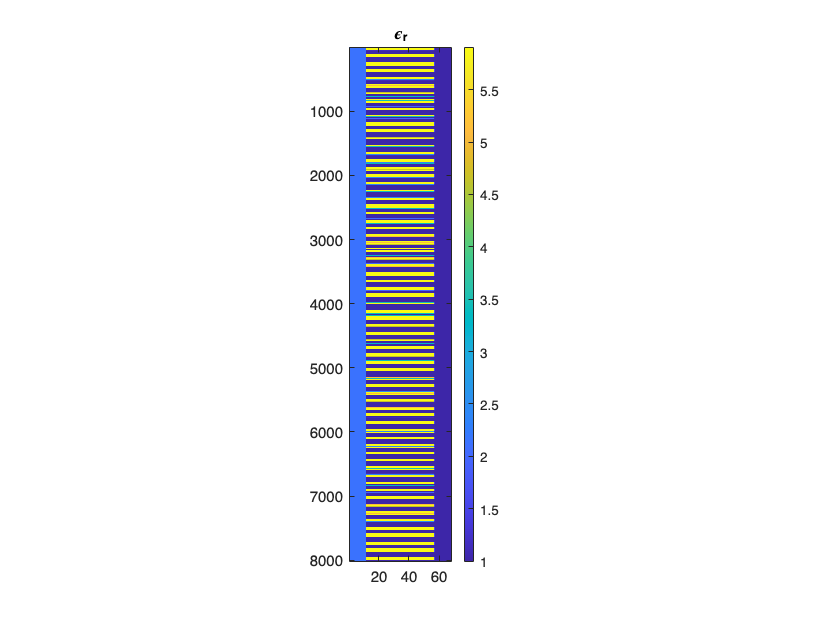

figure; 
    imagesc(syst.epsilon); 
    colorbar; title('\epsilon_r')
    pbaspect([1 5 1])


fprintf('size(syst.epsilon): %s \n',sprintf('%d ', size( syst.epsilon )))

size(syst.epsilon): 8012 68  



max(epsilon_metalens-flipud(epsilon_metalens),[],'all')

ans = 0

max(syst.epsilon-flipud(syst.epsilon),[],'all')

ans = 0

## Build the compressed input-source matrix B  

##                  @@ fft can be slow --> can report the time consumption of fft vs size

time1 = clock;

% Obtain properties of propagating channels on the two sides.
BC = 'periodic';                  % Periodic boundary condition means the propagating channels are plane waves
k0dx = 2*pi/wavelength*dx;        % Dimensionless frequency k0*dx
use_continuous_dispersion = true; % Use continuous dispersion relation for (kx,ky), 
                                  % i.e. kx^2 + ky^2 = epsilon_bg*k0^2 (epsilon_bg = epsilon_L or epsilon_R) 

if center_y == true
    channels_L = mesti_build_channels(ny_L, 'TM', BC, k0dx, epsilon_L, [], use_continuous_dispersion, (ny_L+1)/2);
    channels_R = mesti_build_channels(ny_R, 'TM', BC, k0dx, epsilon_R, [], use_continuous_dispersion, (ny_R+1)/2);
else
    channels_L = mesti_build_channels(ny_L, 'TM', BC, k0dx, epsilon_L, [], use_continuous_dispersion);
    channels_R = mesti_build_channels(ny_R, 'TM', BC, k0dx, epsilon_R, [], use_continuous_dispersion);
end


% We use all propagating plane-wave channels on the right, over width W_out. 
M_R = channels_R.N_prop  % Number of channels on the right               

M_R = 399


% For the incident plane waves (over width W_in) in silica, we only take 
% the ones that can propagate in air. 
% Indices of those channels (among the total channels_L.N_prop channels)

total_num_prop_channels_on_Left = channels_L.N_prop     %( n_air to n_sub in Line168 )

total_num_prop_channels_on_Left = 583


ind_in_L = find(abs(channels_L.kydx_prop/dx) < ( n_air *2*pi/wavelength));
M_L = numel(ind_in_L)  % Number of channels we use on the left             

M_L = 399


% Build the input matrix on the left and right surfaces.
% Note that even though we only need the transmission matrix with input
% from the left, here we also include input channels from the right (same
% as the output channels of interest). This allows us to make matrix K =
% [A,B;C,0] symmetric. The computing time and memory usage of such partial
% factorization can be reduced when matrix K is symmetric.

if do_compression
    % Half the number of extra channels to pad
    % There is no point in having more channels than the number of spatial pixels
    M_L_pad_half = min([floor(ny_L-M_L)/2, round(M_L*pad_ratio_L/2)])    
    M_R_pad_half = min([floor(ny_R-M_R)/2, round(M_R*pad_ratio_R/2)])    
 
    % Total number of channels, including extra padded channels
    N_L = M_L + 2*M_L_pad_half                                           
    N_R = M_R + 2*M_R_pad_half                                           

    % Truncation window size
    ny_window_L = min([ny_L, 1 + round(trunc_width_over_lambda_L*wavelength/dx)])
    ny_window_R = min([ny_R, 1 + round(trunc_width_over_lambda_R*wavelength/dx)])
    
    if  use_B_L_comp_DFT == false % formula

        % Build the compressed input matrix on the left and right surfaces.
        B_L = Alaki_build_compressed_B(ny_L, N_L, ny_window_L, use_Hann_window);
        B_R = Alaki_build_compressed_B(ny_R, N_R, ny_window_R, use_Hann_window);

    else % use_B_L_DFT == true 

        if use_Hann_window == false

            B_L = channels_L.fun_u(channels_L.kydx_prop(ind_in_L));          
            B_R = channels_R.fun_u(channels_R.kydx_prop);                   
    
            % works for both center_y false or true
            B_L = 1/sqrt(N_L) * fftshift( fft( ifftshift( B_L ),[],2 ) ) ;   
            B_R = 1/sqrt(N_R) * fftshift( fft( ifftshift( B_R ),[],2 ) ) ;   

        else % if use_Hann_window == true
            
            if pad_ratio_R == false
                B_L = channels_L.fun_u(channels_L.kydx_prop(ind_in_L))          
                B_R = channels_R.fun_u(channels_R.kydx_prop);                    
        
                % works for both center_y false or true
                B_L = 1/sqrt(N_L) * fftshift( fft( ifftshift( B_L ),[],2 ) ) ;   
                B_R = 1/sqrt(N_R) * fftshift( fft( ifftshift( B_R ),[],2 ) ) ;   
    
                B_L = 0.5*B_L + 0.25*circshift( B_L , 1 , 2 ) + 0.25*circshift( B_L , -1 , 2 );   
                B_R = 0.5*B_R + 0.25*circshift( B_R , 1 , 2 ) + 0.25*circshift( B_R , -1 , 2 );   
            

             else % Padding

                ind_in_L_all_prop = find(abs( channels_L.kydx_all /dx)  < (n_air *2*pi/wavelength));
                ind_in_R_all_prop = find(abs( channels_R.kydx_all /dx)  < (n_air *2*pi/wavelength));
                
                ind_in_L_pad = ind_in_L_all_prop(1)-M_L_pad_half : ind_in_L_all_prop(end)+M_L_pad_half;
                ind_in_R_pad = ind_in_R_all_prop(1)-M_R_pad_half : ind_in_R_all_prop(end)+M_R_pad_half;

                B_L = channels_L.fun_u(channels_L.kydx_all(ind_in_L_pad));      
                B_R = channels_R.fun_u(channels_R.kydx_all(ind_in_R_pad));       
        
                % ????   works for both center_y false or true
                B_L = 1/sqrt(N_L) * fftshift( fft( ifftshift( B_L ),[],2 ) ) ;   
                B_R = 1/sqrt(N_R) * fftshift( fft( ifftshift( B_R ),[],2 ) ) ;   
    
                B_L = 0.5*B_L + 0.25*circshift( B_L , 1 , 2 ) + 0.25*circshift( B_L , -1 , 2 );   
                B_R = 0.5*B_R + 0.25*circshift( B_R , 1 , 2 ) + 0.25*circshift( B_R , -1 , 2 );  


            end

            % Applying window truncation 
            num_trunc_width_L = ceil_odd_N( trunc_width_over_lambda_L * wavelength / dx )
            num_trunc_width_R = ceil_odd_N( trunc_width_over_lambda_L * wavelength / dx )
            x_L = (num_trunc_width_L+1)/2
            x_R = (num_trunc_width_R+1)/2

            mask_L = false(ny_metalens_big, N_L);  % Initialize a mask with all false (0)
            mask_R = mask_L;
            for i = 1:N_L
                [~,ind_L]=max(abs(B_L(:,i)));
                ind_l = max(ind_L-x_L , 1);
                ind_h = min(ind_L+x_L , ny_metalens_big);
                mask_L(ind_l:ind_h , i) = 1;

                [~,ind_R]=max(abs(B_R(:,i)));
                ind_l = max(ind_R-x_R , 1);
                ind_h = min(ind_R+x_R , ny_metalens_big);
                mask_R(ind_l:ind_h , i) = 1;
            end
            B_L = B_L .* mask_L; 
            B_R = B_R .* mask_R; 

        end

    end

else
    % Total number of channels
    N_L = M_L;
    N_R = M_R;

    % Build the input matrix on the left and right surfaces.
    B_L = channels_L.fun_u(channels_L.kydx_prop(ind_in_L));
    B_R = channels_R.fun_u(channels_R.kydx_prop);
end

M_L_pad_half = 100

M_R_pad_half = 100

N_L = 599

N_R = 599

ny_window_L = 401

ny_window_R = 401


clear ind_in_R_pad ind_in_L_pad ind_in_R_all_prop ind_in_L_all_prop

### Build complete B struct

% We take out the -2i prefactor of B, so C will equal transpose(B).
% The flux-normalization prefactor sqrt(nu) will be added later.
opts.prefactor = -2i;

% Preallocate the 2-element structure array B_struct
B_struct = struct('pos', {[],[]}, 'data', {[],[]});

% In mesti(), B_struct.pos = [m1, n1, h, w] specifies the position of a
% block source, where (m1, n1) is the index of the smaller-(y,x) corner,
% and (h, w) is the height and width of the block. Here, we put line
% sources (w=1) on the left surface (n1=n_L) and the right surface
% (n1=n_R) with height ny_L and ny_R centered around the metalens.
n_L = nx_extra_left          % x pixel immediately before the metalens

n_L = 11

n_R = n_L + nx_metalens + 1  % x pixel immediately after the metalens

n_R = 58

m1_L = ny_extra_low + 1      % first y pixel of the metalens

m1_L = 11

m1_R = nPML + 1              % first y pixel of the output projection window

m1_R = 11

B_struct(1).pos = [m1_L, n_L, ny_L, 1];
B_struct(2).pos = [m1_R, n_R, ny_R, 1];

% B_struct.data specifies the source profiles inside such block, with
% B_struct.data(:, a) being the a-th source profile.
B_struct(1).data = B_L;
B_struct(2).data = B_R;

%clear epsilon_metalens B_L B_R; % These are no longer needed, so clear them to save memory.

% Time spent to build the B
time2 = clock; timing_build_B = etime(time2,time1);

### Plotting B_L    

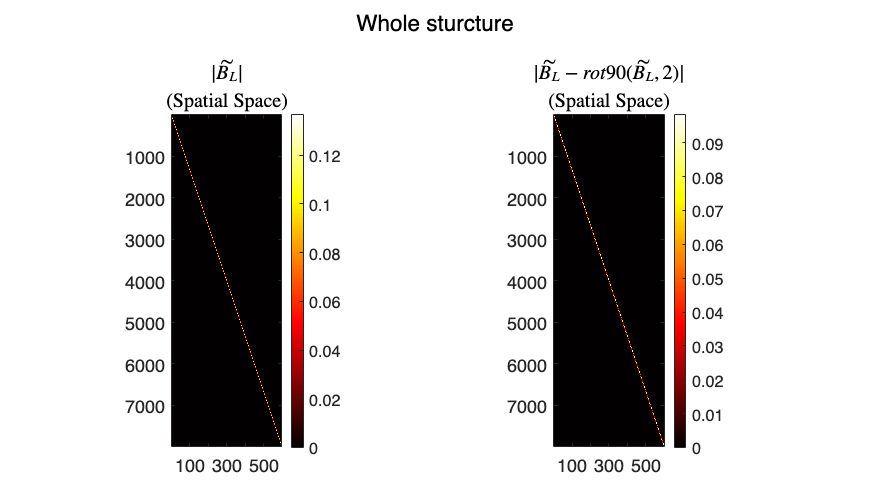

figure1=figure('Position', [1, 1, 700, 400]);
sgtitle('Whole sturcture') 

subplot(1,2,1)
    imagesc(abs(B_L));
    colorbar; colormap 'hot'; set(gcf,'color','w')
    if do_compression
        title('$| \tilde{B_L} |$',{'(Spatial Space)'}, 'Interpreter','latex');
    else
        title({'|B_L|'},{'(Momentum Space)'}) 
    end
    pbaspect([1 3 1]); set(gca,'fontsize',fig_font_size); 


subplot(1,2,2)
    imagesc(abs(B_L - rot90(B_L,2))); 
    colorbar; colormap 'hot'; set(gcf,'color','w')    
    if do_compression
        title({'$| \tilde{B_L}  - rot90(\tilde{B_L},2) |$'},{'(Spatial Space)'}, 'Interpreter','latex'); 
    else
        title({'|B_L - rot90(B_L)|'},{'(Momentum Space)'}); 
    end
    pbaspect([1 3 1]); set(gca,'fontsize',fig_font_size);



% fprintf('max( abs(B_L - rot90(B_L,2)) ,[],''all'' )  ) = \n%e\n' , ...
%     max( abs(B_L - rot90(B_L,2)) ,[],'all' ) )


max( abs(B_L - flipud(fliplr(B_L))) ,[],'all' ) 

ans =    (1,1)       0.0984


size(B_L)

ans =         7992         599



B_L_big = B_L;
B_R_big = B_R;

NL_big = N_L

NL_big = 599

NR_big = N_R

NR_big = 599


clear B_L B_R

## Compute S

tic
C = 'transpose(B)';        % Specify C = transpose(B)
D = [];                    % We only need the transmission matrix, for which D=0
opts.clear_syst = true;    % syst can be cleared in mesti()
opts.clear_BC = true;      % B can be cleared in mesti()
tic
[S, info] = mesti(syst, B_struct, C, D, opts);

System size: ny = 8012, nx = 68; Ez polarization
UPML on -x +x -y +y sides; xBC = PEC; yBC = PEC
Building B,C... elapsed time:   0.004 secs
Building A  ... elapsed time:   0.071 secs
< Method: APF using MUMPS with AMD ordering (symmetric K) >
Building K  ... elapsed time:   0.036 secs
Analyzing   ... elapsed time:   0.198 secs
Factorizing ... elapsed time:   1.043 secs
          Total elapsed time:   1.368 secs


toc

Elapsed time is 1.370157 seconds.


### Extract $t_L$ from S

time1 = clock;

% The full scattering matrix is S = [r_L,t_R;t_L,r_R]
% Extract the transmission matrix from left to right, t_L
ind_L = 1:N_L;
ind_R = (N_L+1):(N_L+N_R);
t = S(ind_R,ind_L); 
clear S; % It is no longer needed, so clear it to save memory.

t_spatial_big = t;
toc

Elapsed time is 1.373894 seconds.


### Plot $t_{spatial}$

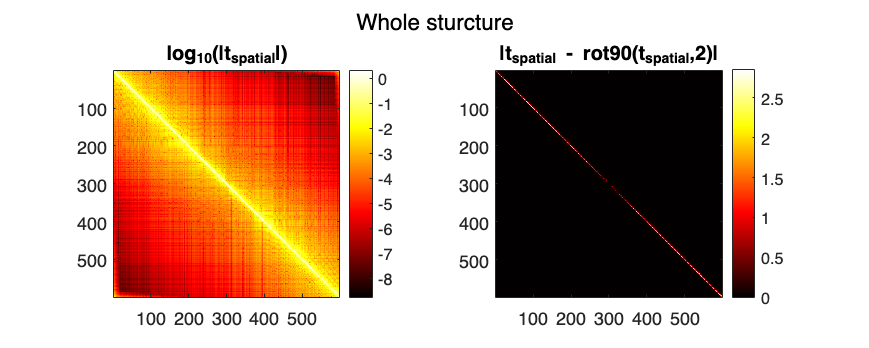

figure1=figure('Position', [1, 1, 1000, 400]);
sgtitle('Whole sturcture') 

subplot(1,2,1)
    imagesc( log10(abs(t_spatial_big))); 
    colorbar; colormap 'hot'; pbaspect([1 1 1]);
    set(gca,'fontsize',fig_font_size);  set(gcf,'color','w')
    title({'log_{10}(|t_{spatial}|)'})


subplot(1,2,2)
    imagesc(abs(t_spatial_big - rot90(t_spatial_big,2))); 
    colorbar; colormap 'hot'; pbaspect([1 1 1]);
    set(gca,'fontsize',fig_font_size);  set(gcf,'color','w')
    title({'|t_{spatial} - rot90(t_{spatial},2)|'})

  
fprintf('max( abs(t_spatial - rot90(t_spatial,2)) ,[],''all'' ) = \n%e\n' , ...
    max( abs(t_spatial_big - rot90(t_spatial_big,2)) ,[],'all' ) )

max( abs(t_spatial - rot90(t_spatial,2)) ,[],'all' ) = 
2.853589e+00


# Big sturcture on Focal plane

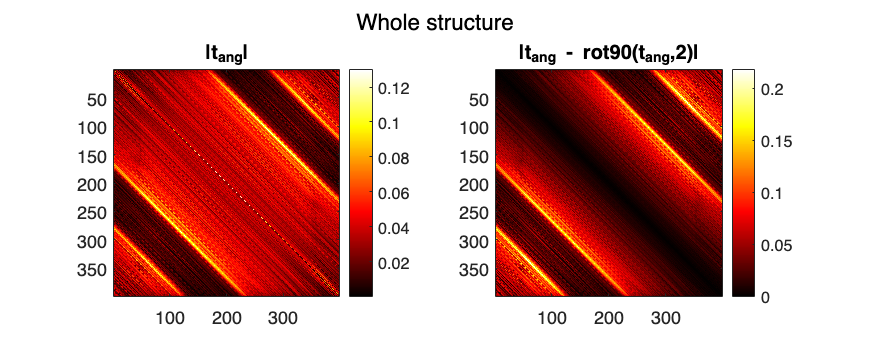

ans = 1.2285

ans = 0.1299

max( abs(t_ang - rot90(t_ang,2)) ,[],'all' ) = 

ans = 0.2185


figure1=figure('Position', [1, 1, 1000, 400]);
sgtitle('Whole structure');

[t_angular_big,sqrt_nu_R] =  Calc_t_angular...
                            (N_R, N_L, M_L, M_R, M_L_pad_half, M_R_pad_half,...
                            ind_in_L, channels_L ,channels_R ,t_spatial_big, ...
                            do_compression ,use_Hann_window , fig_font_size);

ky_ASP NOT Symm

ans = logical
   1


ans = logical
   0


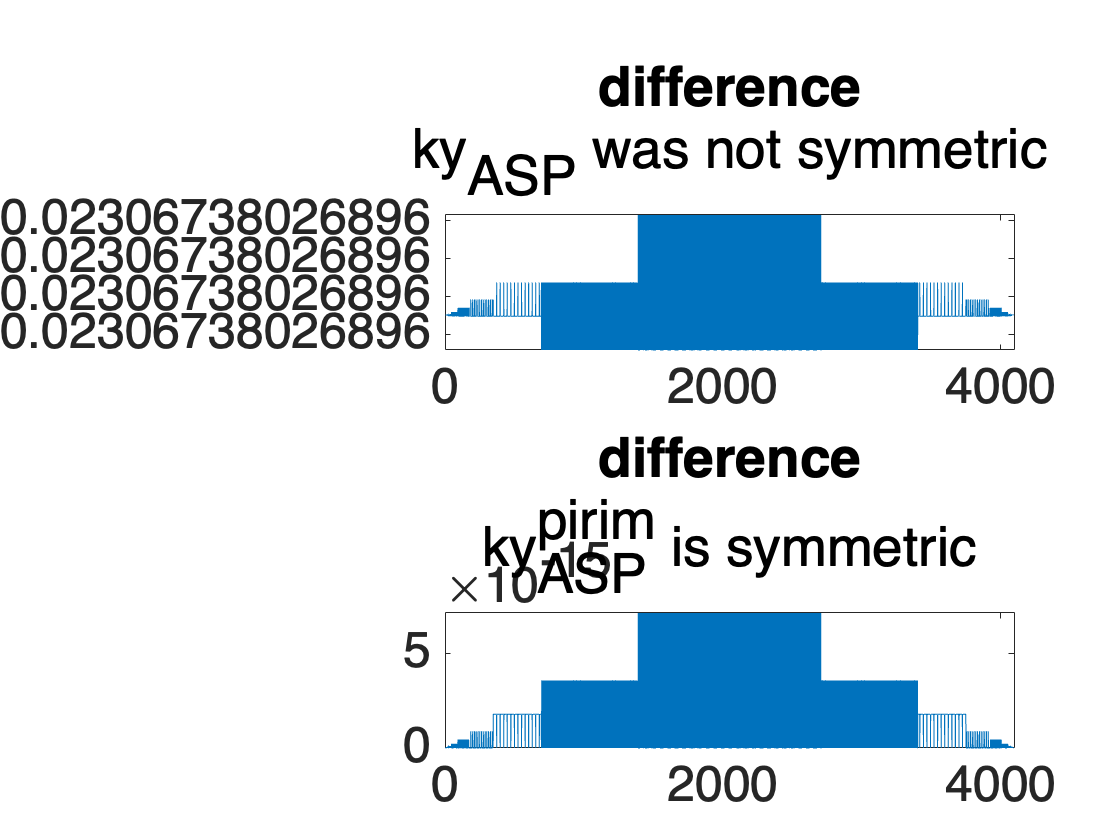

ind_angle_middle = 40

chosen theta_in = 0.000000

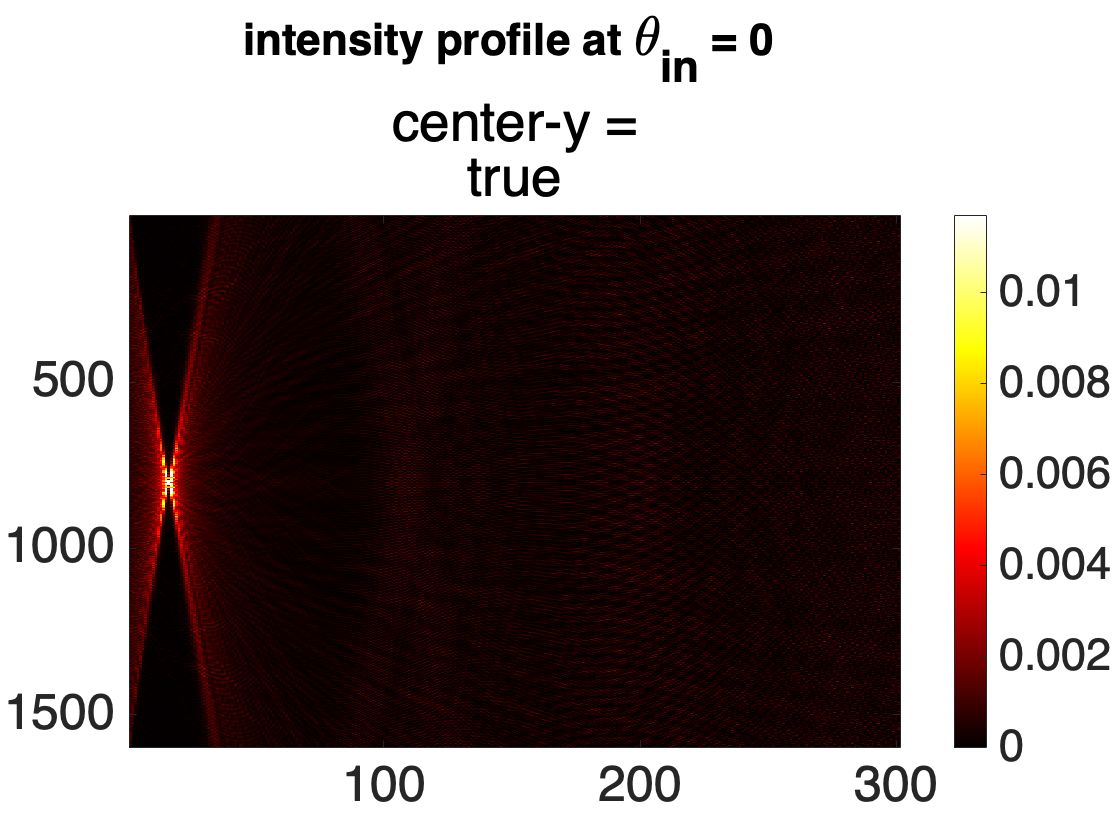



[theta_in_list , T_list_big , SR_list_big] = Calc_T_SR_focal_plane(...
                  t_angular_big ,focal_length, M_L, M_R,ind_in_L, channels_L ,channels_R,...
                  W, dx ,ny_R ,ny_L, n_air, wavelength ,n_silica ,ny_metalens_big,...
                  ny_R_extra_half, center_y,sqrt_nu_R,plot_fig);

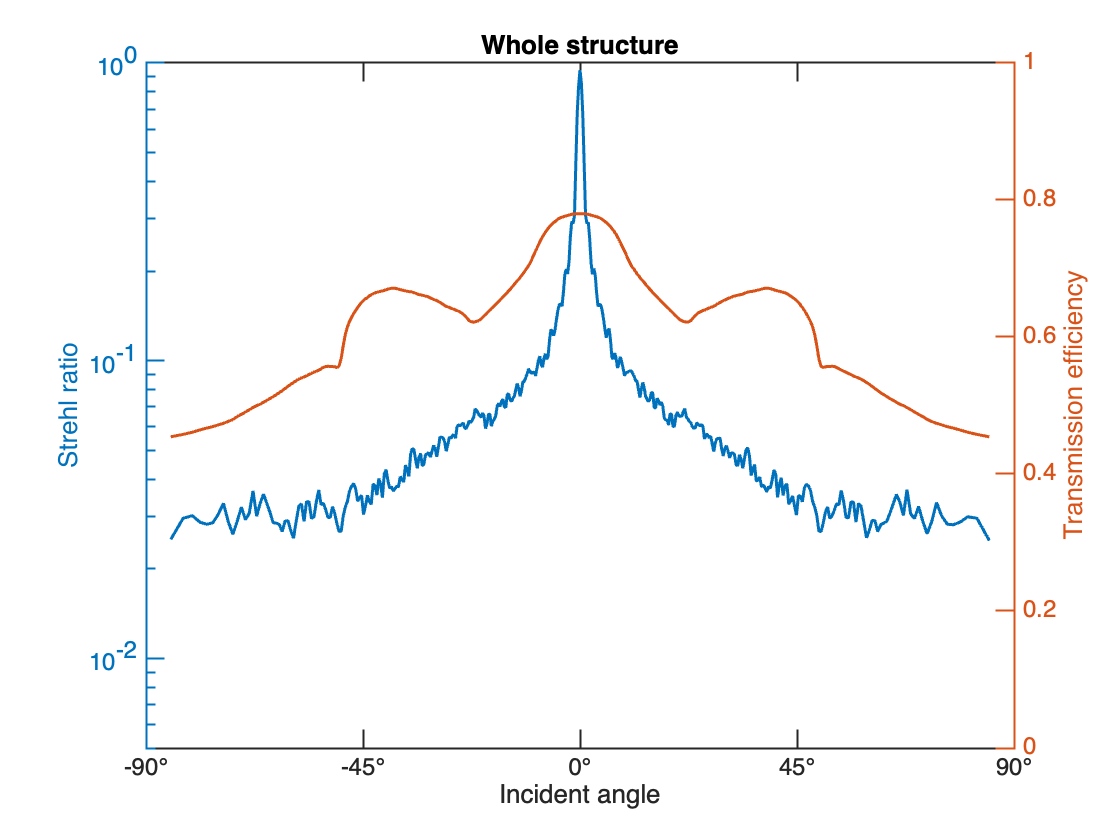

title('Whole structure');



y_in_over_wavelength = linspace(-W/2,W/2, length(t_spatial_big))/wavelength;


clear B_L  B_R B_R_big big_temp epsilon_metalens  epsilon_seg ind_L ind_R indx_ny_seg ...
      D indx_strt_end_segs indx indic seg seg_only seg_partial zz_1 zz_2 delta_y_big t_spatial ...
      ans  epsilon_L epsilon_R t_spatial_segments

# Functions

function seg_partial = stitching_2(  seg , num_seg  , n_overlap_seg1 , n_overlap_seg2 , seg_cnt , n_sec)

    seg_mirror = fliplr(seg);

     
    if seg_cnt == 1
      seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg2 ) , -((n_sec - n_overlap_seg2):n_sec-1) , seg_mirror  )); 
%         seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg2 ) , (n_sec - n_overlap_seg2+1):n_sec , seg_mirror )); 

    elseif seg_cnt == num_seg
        if num_seg == 2
            seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg1+1-1 ) , (n_sec - n_overlap_seg1+1):n_sec , seg_mirror )); 
        else
            seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg1+1 ) , (n_sec - n_overlap_seg1):n_sec , seg_mirror )); 
        end


    elseif seg_cnt <= (num_seg/2) % <=
        seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg2+1-1 ) , (n_sec - n_overlap_seg2+1):n_sec , seg_mirror )); 
        seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg1+2 ) , -((n_sec - n_overlap_seg1):n_sec+1) , seg_mirror_partial  ));  
        

    elseif seg_cnt > ceil(num_seg/2)
        if rem(num_seg , 2) == 0 && seg_cnt == num_seg/2+1
            seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg2+1-1 ) , (n_sec - n_overlap_seg2+1):n_sec , seg_mirror )); 
            seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg1+2-1 ) , -((n_sec - n_overlap_seg1+1):n_sec+1) , seg_mirror_partial  ));
        else
            seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg2+1 ) , (n_sec - n_overlap_seg2):n_sec , seg_mirror )); 
            seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg1+2-1 ) , -((n_sec - n_overlap_seg1+1):n_sec+1) , seg_mirror_partial  ));
        end

     elseif rem(num_seg,2) == 1
        if seg_cnt == (num_seg+1)/2
            seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg2+1-1 ) , (n_sec - n_overlap_seg2+1):n_sec , seg_mirror ));  
            seg_mirror_partial = full(spdiags( zeros( n_sec , n_overlap_seg1+2-1 ) , -((n_sec - n_overlap_seg1+1):n_sec+1) , seg_mirror_partial  )); 
        end


    end
    seg_partial = fliplr(seg_mirror_partial);
    
end


%%%%%%%%%%%%
function NL_big_calc = N_L_finder(W_tot_over_wavelenght, wavelength , pad_big)
  
    N0 = (W_tot_over_wavelenght*wavelength) / (wavelength/2) ; 

    if N0-floor(N0) == 0        
        if rem(N0 , 2) == 0
            N0_final = N0 + 1; % -1
        else
            N0_final = N0;
        end
            
    elseif rem(floor(N0) , 2) == 0
        N0_final = floor(N0) + 1;
      
    elseif rem(floor(N0) , 2) == 1
        N0_final = floor(N0) + 2; % +0

    end
    
    NL_big_calc = N0_final + 2*round(N0_final*pad_big/2);
end


%%%%%%%%%%%%
function []=plot_1D_Schematic(ny_metalens_big , ind_start_end_segs , num_seg)
    mat_Schemat = zeros(ny_metalens_big , ceil(num_seg/2));
    
    for seg_cnt=1:num_seg/2 
        indx = ind_start_end_segs(seg_cnt,1):ind_start_end_segs(seg_cnt,2) ;
        mat_Schemat(indx,seg_cnt) = seg_cnt;
        indx = ind_start_end_segs(num_seg-seg_cnt+1,1):ind_start_end_segs(num_seg-seg_cnt+1,2) ;
        mat_Schemat(indx,seg_cnt) = seg_cnt;
    end
    if rem(num_seg,2) == 1
        indx = ind_start_end_segs((num_seg+1)/2,1):ind_start_end_segs((num_seg+1)/2,2) ;
        mat_Schemat(indx,end) = (num_seg+1)/2;
    end

    figure; 
        imagesc(mat_Schemat)
        if mod(num_seg,2) == 0
            yline(round(ny_metalens_big/2));
        end

    fprintf('max( 2D_Schem - rot90(2D_Schem,2) ) = %.6f '...
           , max(mat_Schemat - flip(mat_Schemat) , [] , 'all'))
end


function []=plot_2D_Schematic(ny_metalens_big , ind_start_end_segs , num_seg)
    mat_Schemat = zeros(ny_metalens_big , ny_metalens_big);
    
    for seg_cnt=1:num_seg/2 
        indx = ind_start_end_segs(seg_cnt,1):ind_start_end_segs(seg_cnt,2) ;
        mat_Schemat(indx,indx) = seg_cnt;
        indx = ind_start_end_segs(num_seg-seg_cnt+1,1):ind_start_end_segs(num_seg-seg_cnt+1,2) ;
        mat_Schemat(indx,indx) = seg_cnt;
    end
    if rem(num_seg,2) == 1
        indx = ind_start_end_segs((num_seg+1)/2,1):ind_start_end_segs((num_seg+1)/2,2) ;
        mat_Schemat(indx,indx) = (num_seg+1)/2;
    end
        
    figure;
        imagesc(mat_Schemat); 
    
    fprintf('max( 2D_Schem - rot90(2D_Schem,2) ) = %.6f ' ...
           , max(mat_Schemat - rot90(mat_Schemat,2) , [] , 'all'))   

   
end


%%%%%%%%%%%%
function fl_odd_N = floorodd(N)

    fl_N = floor(N);
    if rem(fl_N,2) == 1
        fl_odd_N = fl_N;
    else
        fl_odd_N = fl_N - 1;
    end

end

%%%%%%%%%%%%
function cl_odd_N = ceil_odd_N(N)

    fl_N = ceil(N);
    if rem(fl_N,2) == 1
        cl_odd_N = fl_N;
    else
        cl_odd_N = fl_N + 1;
    end

end